clear

## 数据输入

% 母线（节点）信息
Nodes_old=["GEN1","GEN2","GEN3","GEN1-230","GEN2-230","GEN3-230","STNA-230","STNB-230","STNC-230"]; %名称
NodeType_old=["Slack","PV","PV","PQ","PQ","PQ","PQ","PQ","PQ"];%节点类型

%负荷信息
Load=["STNA-230","STNB-230","STNC-230"]; %负荷对应母线
LD_P=[-1.25,-0.9,-1.00]; %有功负荷
LD_Q=[-0.5,-0.3,-0.35]; %无功负荷

%转移节点信息
transNodes=["GEN1-230","GEN2-230","GEN3-230"];

%发电机信息
Gen=["GEN1","GEN2","GEN3"]; %发电机对应母线
GE_P=[0,1.63,0.85];     %有功发电
GE_V=[1.04,1.025,1.025];   %母线电压幅值
GE_theta=[0];    %母线电压相角

%交流线信息
AC_I=["GEN1-230","STNA-230","GEN2-230","STNC-230","GEN3-230","STNB-230","GEN1","GEN2","GEN3"]; %I侧节点
AC_J=["STNA-230","GEN2-230","STNC-230","GEN3-230","STNB-230","GEN1-230","GEN1-230","GEN2-230","GEN3-230"]; %J侧节点
AC_Z=[0.01+0.085j,0.032+0.161j,0.0085+0.072j,0.0119+0.1008j,0.039+0.17j,0.017+0.092j,0.0576j,0.0625j,0.05860j];%I-J阻抗
AC_y=[0.088j,0.153j,0.0745j,0.1045j,0.179j,0.079j,0,0,0];%I-J对地导纳参数

%变压器信息
Trans_I=["GEN1","GEN2","GEN3"]; %k侧节点
Trans_J=["GEN1-230","GEN2-230","GEN3-230"]; %非k侧节点
Trans_k=[1,1,1]; %变比

## 潮流计算

m=10; %总共计算次数
steps=0.1;%步长
GE_P(2)=GE_P(2)-steps*0.5*m;%初值

for i=1:m
    %调整发电机的有功输出
    GE_P(2)=GE_P(2)+steps;
    P_GEN2(i)=GE_P(2);
    %节点数据重排序 生成标准格式
    [Nodes,P_s,Q_s,V0,theta0,n,n_pq,n_pv,n_bal]=DataProcess(Nodes_old,NodeType_old,Load,LD_P,LD_Q,transNodes,Gen,GE_P,GE_V,GE_theta);
    %生成节点导纳矩阵
    [G,B]=GenerateY(Nodes,AC_I,AC_J,AC_Z,AC_y,Trans_I,Trans_J,Trans_k);
    eps=1e-5;
    %迭代计算 并计时
    tStart=tic;
    [V,sita,V_vis,sita_vis]=powerFlowPQCalcu(n,n_pq,n_pv,n_bal,V0,theta0,G,B,P_s,Q_s,eps);
    
    V_exp(i,:)=V;
    theta_exp(i,:)=sita;
    
    %计算交流线路上的潮流 I侧参数
    
    for j=1:length(AC_I)
        indexI=find(Nodes==AC_I(j)); %当前在I侧遍历的节点对应Nodes的位置
        indexJ=find(Nodes==AC_J(j));%当前在J侧遍历的节点对应Nodes的位置
        
        F_AC(i,j)=((V(indexI)-V(indexJ))/AC_Z(j))-V(indexI)*AC_y(j);
    end
    
    tEnd=toc(tStart);
end

    1.0000         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0
         0         0    1.0000         0         0         0         0         0
   -0.2952   -0.1686         0    1.0000         0         0         0         0
   -0.2674         0   -0.1740   -0.2404    1.0000         0         0         0
         0   -0.3865   -0.3047   -0.1789   -0.1996    1.0000         0         0
         0   -0.4514         0   -0.2090   -0.0573   -0.4797    1.0000         0
         0         0   -0.5314         0   -0.2625   -0.4089   -0.5997    1.0000

    0.0000
         0
   -0.0000
   -1.2500
   -0.9000
   -1.0000
    1.2000
    0.8293

    1.0000         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0
         0         0    1.0000         0         0         0         0         0
   -0.2952   -0.168

## 可视化

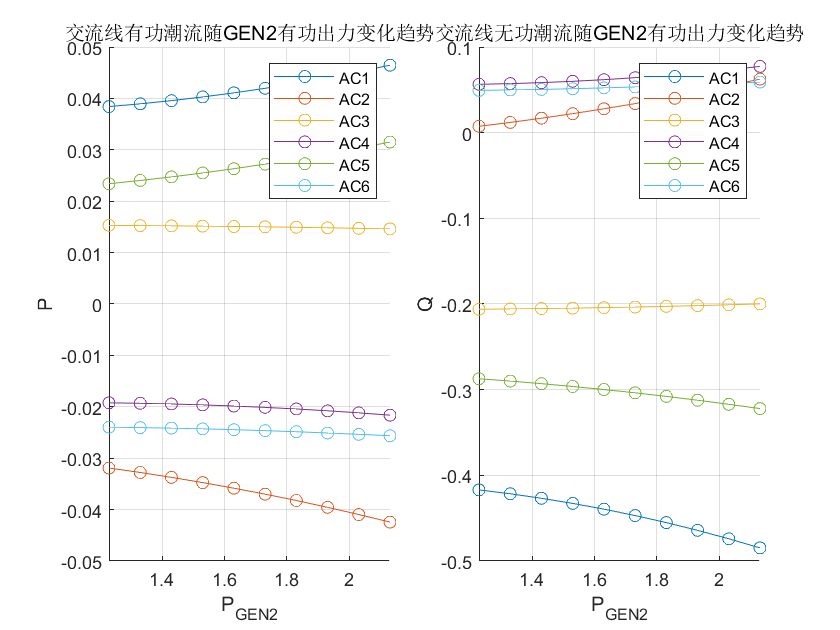

figure(1)
subplot(1,2,1)
hold on
grid on
plot(P_GEN2,real(F_AC(1:10,1)),'Marker',"o"');
plot(P_GEN2,real(F_AC(1:10,2)),'Marker',"o"');
plot(P_GEN2,real(F_AC(1:10,3)),'Marker',"o"');
plot(P_GEN2,real(F_AC(1:10,4)),'Marker',"o"');
plot(P_GEN2,real(F_AC(1:10,5)),'Marker',"o"');
plot(P_GEN2,real(F_AC(1:10,6)),'Marker',"o"');
title("交流线有功潮流随GEN2有功出力变化趋势")
xlabel("P_{GEN2}")
ylabel("P")
legend("AC1","AC2","AC3","AC4","AC5","AC6")
subplot(1,2,2)
hold on
grid on
plot(P_GEN2,imag(F_AC(1:10,1)),'Marker',"o"');
plot(P_GEN2,imag(F_AC(1:10,2)),'Marker',"o"');
plot(P_GEN2,imag(F_AC(1:10,3)),'Marker',"o"');
plot(P_GEN2,imag(F_AC(1:10,4)),'Marker',"o"');
plot(P_GEN2,imag(F_AC(1:10,5)),'Marker',"o"');
plot(P_GEN2,imag(F_AC(1:10,6)),'Marker',"o"');
title("交流线无功潮流随GEN2有功出力变化趋势")
xlabel("P_{GEN2}")
ylabel("Q")
legend("AC1","AC2","AC3","AC4","AC5","AC6")
hold off

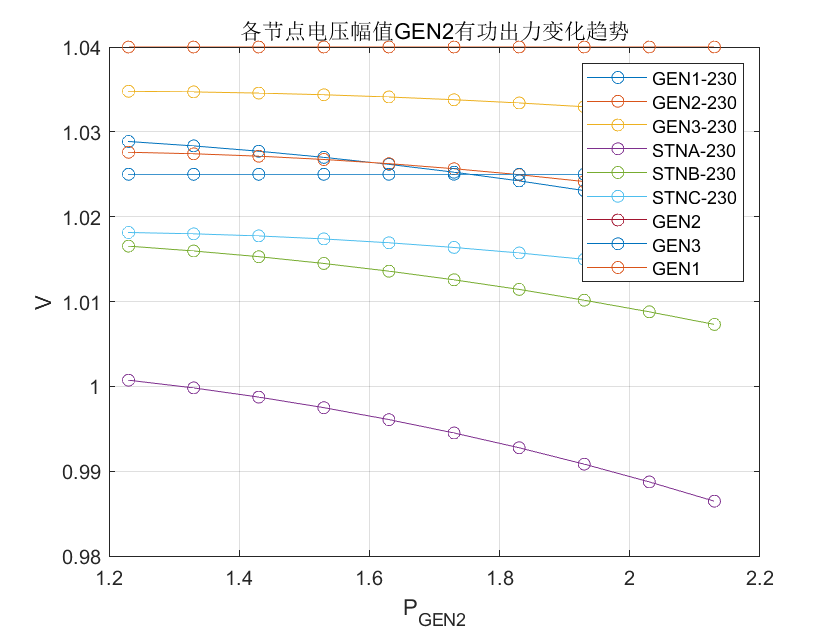


figure(3)
for i=1:length(V_exp(1,:))
    plot(P_GEN2,V_exp(:,i),'Marker',"o");
    hold on 
    if i==length(V_exp)-1
        legend("GEN1-230","GEN2-230","GEN3-230","STNA-230","STNB-230","STNC-230","GEN2","GEN3","GEN1");

    end
end
grid on
title("各节点电压幅值GEN2有功出力变化趋势")
xlabel("P_{GEN2}")
ylabel("V")

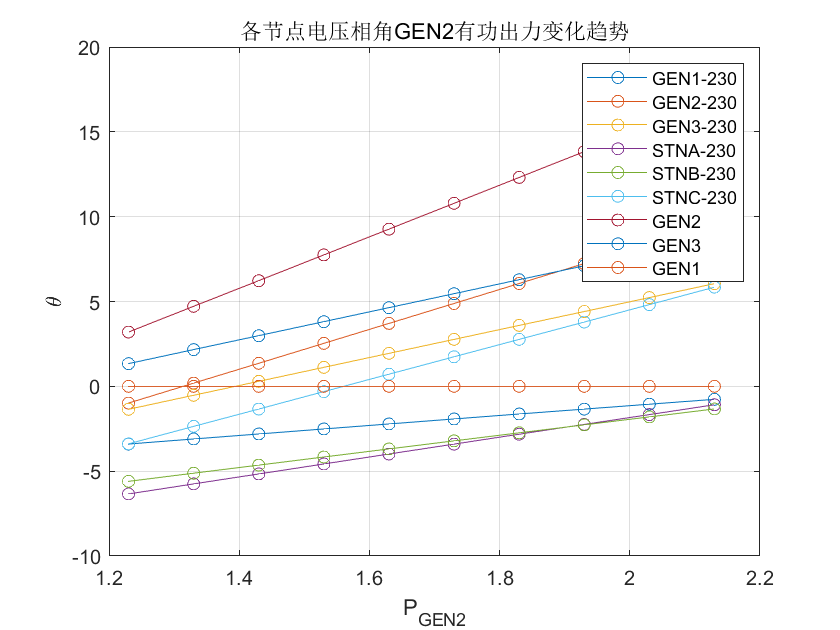


figure(4)
for i=1:length(theta_exp(1,:))
    plot(P_GEN2,theta_exp(:,i),'Marker',"o");
    hold on 
    if i==length(theta_exp)-1
        legend("GEN1-230","GEN2-230","GEN3-230","STNA-230","STNB-230","STNC-230","GEN2","GEN3","GEN1");

    end
end
grid on
title("各节点电压相角GEN2有功出力变化趋势")
xlabel("P_{GEN2}")
ylabel("\theta")